%% LOAD DATA FROM CSV
disp('Loading data from CSV...')

Loading data from CSV...



T = readtable('madrigal_data.csv');

lat_all = T.lat;
lon_all = T.lon;
alt_all = T.alt;
ne_all  = T.Ne;
% kp    = T.kp;

% Replace fill value with NaN
ne_all(ne_all == -1.0) = NaN;
ne_all = ne_all / 1e6;

%FIND PEAK Ne AND PEAK ALTITUDE PER LAT/LON
lat_lon = unique([lat_all, lon_all], 'rows');

peak_ne  = NaN(size(lat_lon,1), 1);
peak_alt = NaN(size(lat_lon,1), 1);

for i = 1:size(lat_lon,1)
    mask = (lat_all == lat_lon(i,1)) & (lon_all == lat_lon(i,2));
    ne_prof  = ne_all(mask);
    alt_prof = alt_all(mask);

    if all(isnan(ne_prof)), continue; end

    [peak_ne(i), idx] = max(ne_prof, [], 'omitnan');
    peak_alt(i) = alt_prof(idx);
end

valid = ~isnan(peak_ne);
peak_ne  = peak_ne(valid);
peak_alt = peak_alt(valid);
peak_lat = lat_lon(valid, 1);
peak_lon = lat_lon(valid, 2);

fprintf('Peak Ne range:  %.2e  to  %.2e cm⁻³\n', min(peak_ne), max(peak_ne))

Peak Ne range:  1.21e+05  to  2.69e+06 cm⁻³


fprintf('Peak Alt range: %.0f  to  %.0f km\n',   min(peak_alt), max(peak_alt))

Peak Alt range: 275  to  525 km


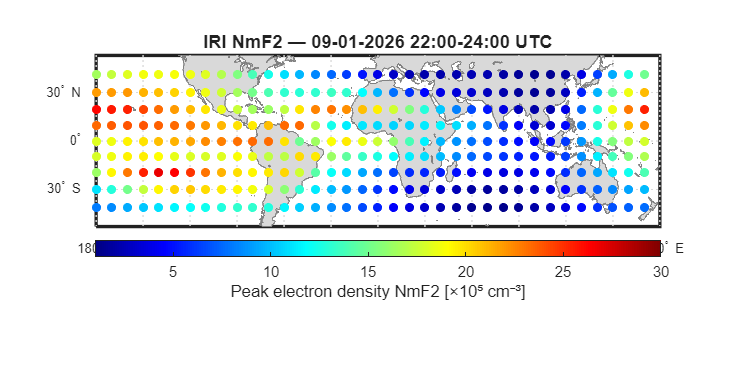


%COLOUR MAPPING
peak_ne_scaled = peak_ne / 1e5;  
vmin = 1;   vmax = 30; 

cmap   = jet(256); 
ne_clamped = max(vmin, min(vmax, peak_ne_scaled));
ci     = round((ne_clamped - vmin) / (vmax - vmin) * 255) + 1; 
colors = cmap(ci, :);             

%PLOT
fig = figure('Name', 'IRI NmF2 Map', 'NumberTitle','off', ...
             'Color','white', 'Position',[100 100 1200 600]);

% World basemap
ax = worldmap([-50 50], [-180 180]);
setm(ax, 'MeridianLabel','on', 'ParallelLabel','on', ...
         'MLabelParallel','south', 'FontSize', 8);
land = shaperead('landareas', 'UseGeoCoords', true);
geoshow(ax, land, 'FaceColor',[0.85 0.85 0.85], 'EdgeColor',[0.5 0.5 0.5]);

% Scatter the NmF2 points
scatterm(ax, peak_lat, peak_lon, 30, colors, 'filled', ...
         'MarkerEdgeColor','none');

% Colorbar
cb = colorbar(ax, 'southoutside');
colormap(ax, cmap);
clim([vmin vmax]);
cb.Label.String = 'Peak electron density NmF2 [×10⁵ cm⁻³]';
cb.Label.FontSize = 10;

% Title with statistics
avg_nmf2 = mean(peak_ne, 'omitnan');
avg_hmf2 = mean(peak_alt, 'omitnan');
title(ax, sprintf('IRI NmF2 — %02d-01-2026 22:00-24:00 UTC', ...
      day), 'FontSize', 11);

% Gridlines
gridm('on');

%SAVE
exportgraphics(fig, sprintf('%02d0126 IRI NmF2 Map_V2.png',day), 'Resolution', 300);

fprintf('Map saved as ne_map.png\n')

Map saved as ne_map.png


fprintf('Average NmF2: %.3e cm⁻³\n', avg_nmf2)

Average NmF2: 1.242e+06 cm⁻³


fprintf('Average hmF2: %.0f km\n',    avg_hmf2)

Average hmF2: 377 km
